clear variables

load('lab9_1.mat');

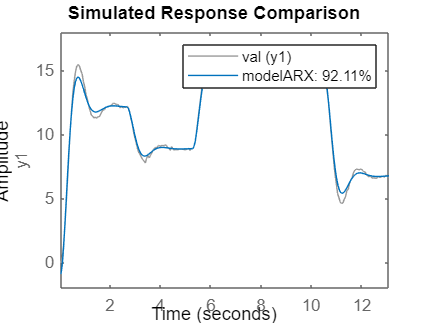


u_id = id.InputData;
y_id = id.OutputData;
u_val = val.InputData;
y_val = val.OutputData;

na = n;
nb = n;
nk = 1;

modelARX = arx(id,[na nb nk]);
compare(modelARX, val);


%build phi matrix for the linear regression
N = length(y_val);
phi = zeros(N, na+nb);

%we try to split the phi matrix into 2 matrices and build each one separately
%build the y elements
for i = 1 : 1 : N
    for j = 1 : 1 : na
        if (i <= j) %if the element is above or on the main diagonal
            phi(i,j) = 0;
        else %if the element is under the main diagonal
            phi(i,j) = -y_val(i-j);
        end
    end
end
% build the u elements
for i = 1 : 1 : N
    for j = (na+1) : 1 : (na+nb)
        if (i <= j-na) %if the element is above or on the main diagonal
            phi(i,j) = 0;
        else %if the element is under the main diagonal
            phi(i,j) = u_val(i-j+na);
        end
    end
end

## prediction

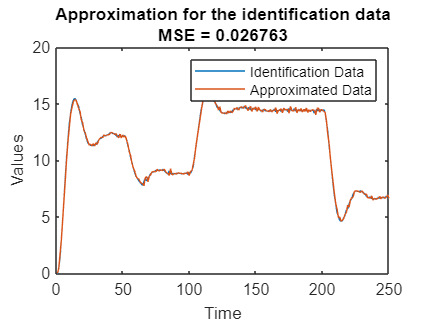

%find the approximation and plot it 
theta = phi \ y_val;
y_pred = phi * theta;

%calculate the MSE
err_squared_id = (y_val - y_pred) .^ 2;
MSE_id = (1/N) * sum(err_squared_id);

figure
plot(y_val);
hold on
plot(y_pred);
title("Approximation for the identification data"  + newline + "MSE = " + MSE_id)
legend("Identification Data", "Approximated Data");
xlabel('Time')
ylabel('Values')

## simulation

phi_sim = zeros(N, na+nb);

%calculate the simulation y by using the previous values

y_sim = zeros(N,1);

for i = 2 : 1 : N
    %for the elements with y
    for j = 1 : 1 : na
        if (i > j)
            phi_sim(i,j) = -y_sim(i-j);
        end
    end
    %for the elements with u
    for j = (na+1) : 1 : (na+nb)
        if (i > j-na)
            phi_sim(i,j) = u_val(i-j+na);
        end
    end
%find the simulation data
y_sim(i) = phi_sim(i,:) * theta;
end

## Build the instrument vector Z

Z = zeros(N,na+nb);

for i = 1 : 1 : N
    for j = 1 : 1 : na
        if (i <= j)
            Z(i,j) = 0;
        else
            Z(i,j) = -y_sim(i-j);
        end
    end
    for j = 1 : 1 : nb
        if (i <= j)
            Z(i,j+na) = 0;
        else
            Z(i,j+na) = u_val(i-j);
        end
    end
end
Z = transpose(Z);
phi = transpose(phi);

## Computing PHI tilda and Y tilda

Y_tilda = zeros(na+nb,1);
PHI_tilda = zeros(na+nb,na+nb);
 
for k = 1 : 1 : N
    Y_tilda = Y_tilda + Z(:,k)*y_val(k);
    PHI_tilda = PHI_tilda + Z(:,k)*transpose(phi(:,k));
end 
Y_tilda = 1/N * Y_tilda;
PHI_tilda = 1/N * PHI_tilda;

## Obtaining theta by linear regression procedure

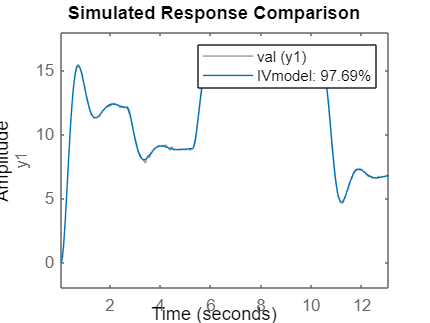

theta_tilda = PHI_tilda \ Y_tilda; % L.R.
IVmodel = idpoly([1 transpose(theta_tilda(1:na))], [0 transpose(theta_tilda(na+1:na+nb))], [], [], [], 0, val.Ts);

figure,
compare(IVmodel,val);